## Объект 1 и 2. ДПТ

% Параметры двигателя постоянного тока
km = 0.3509;
ke = 0.3509;
J = 0.0025;
R = 4.7320;
L = 1.091;

xi = R*sqrt(J)/2/sqrt(L*ke*km);
T_simp = (J * R) / (km * ke);
K = 1/ke;
T_full = sqrt(J*L/(ke*km));
alpha = -xi / T_full;
omega = sqrt(1-xi^2)/T_full;
beta = xi/ sqrt(1-xi^2);

% Передаточная функция полной модели
num_full = [km];
den_full = [J * L, J * R, km * ke];
sys_full = tf(num_full, den_full);

% Передаточная функция упрощенной модели
num_simplified = [km / R];
den_simplified = [J, km * ke / R];
sys_simplified = tf(num_simplified, den_simplified);

% Временной вектор для аналитического решения
t = linspace(0, 5, 100);

% Аналитическое решение для переходного отклика
omega_anal_simp_impulse = (K/T_simp) * exp(-t/T_simp);
omega_anal_simp_step = K * (1- exp(-t/T_simp));

omega_anal_full_impulse = K/(T_full*sqrt(1-xi^2))*exp(-xi/T_full*t).*sin(t/T_full.*sqrt(1-xi^2));
omega_anal_full_step =K-K.*exp(alpha*t).*(cos(omega*t)+beta.*sin(omega*t));


% ---- График импульсного отклика для упрощенной модели ----
figure;
impulse(sys_simplified, 'r');

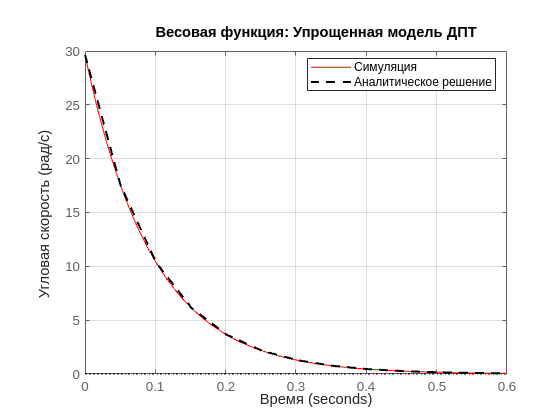

hold on;
plot(t, omega_anal_simp_impulse, 'k--', 'LineWidth', 1.5); % Аналитическое решение
title('Весовая функция: Упрощенная модель ДПТ');
legend('Симуляция', 'Аналитическое решение', "Location", "best");
xlabel('Время');
ylabel('Угловая скорость (рад/с)');
grid on;
exportgraphics(gcf, 'figs/task_1_impl.png', 'Resolution', 300);

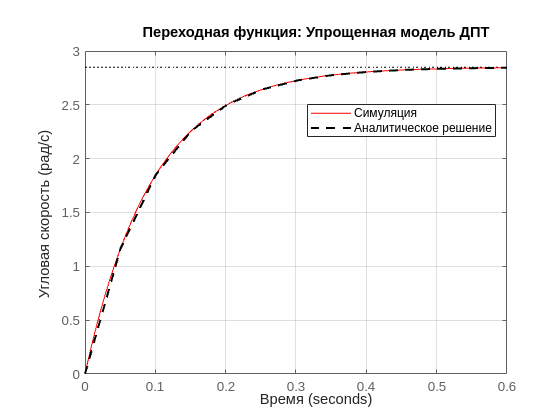


% ---- График переходного отклика для упрощенной модели ----
figure;
step(sys_simplified, 'r');
hold on;
plot(t, omega_anal_simp_step, 'k--', 'LineWidth', 1.5); % Аналитическое решение
title('Переходная функция: Упрощенная модель ДПТ');
legend('Симуляция', 'Аналитическое решение', "Location", "best");
xlabel('Время');
ylabel('Угловая скорость (рад/с)');
grid on;
exportgraphics(gcf, 'figs/task_1_step.png', 'Resolution', 300);

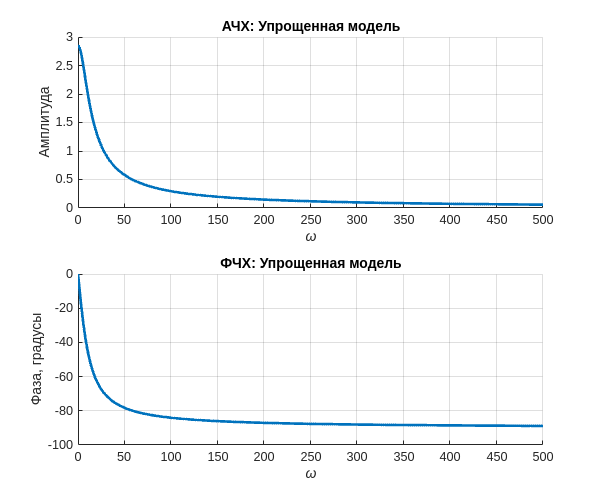

% ---- График АФЧХ для упрощенной модели ----
omega = linspace(0, 500, 100000);

a = K./sqrt(1+omega.^2*T_simp^2);
phi = atan2(-omega*T_simp*K./(1+omega.^2*T_simp^2), K./(1+omega.^2*T_simp^2));
L = 20*log10(a);

figure('Position', [0 0 600 500]);

subplot(2, 1, 1)
hold on;
plot(omega, a, 'LineWidth', 2);
title('АЧХ: Упрощенная модель');
xlabel('\omega');
ylabel('Амплитуда');
grid on;

subplot(2, 1, 2)
hold on;
plot(omega, phi/pi*180, 'LineWidth', 2);
title('ФЧХ: Упрощенная модель');
xlabel('\omega');
ylabel('Фаза, градусы');
grid on;

exportgraphics(gcf, 'figs/task_1_АФЧХ.png', 'Resolution', 300);

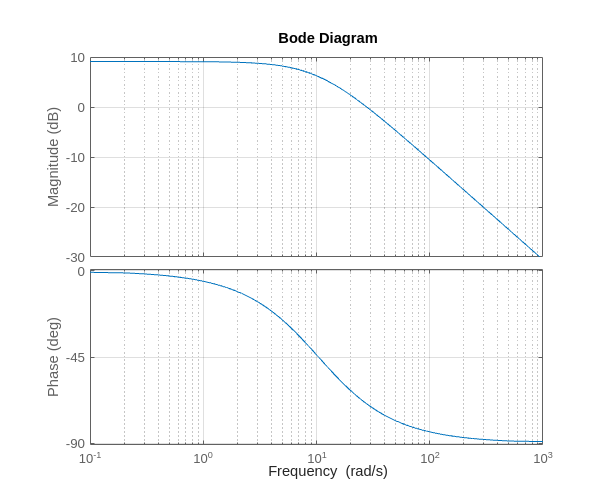

% Построение Bode Plot
figure('Position', [0 0 600 500]);
bode(sys_simplified);
grid on;   % Добавить сетку для удобства чтения графиков
exportgraphics(gcf, 'figs/task_1_ЛАФЧХ.png', 'Resolution', 300);

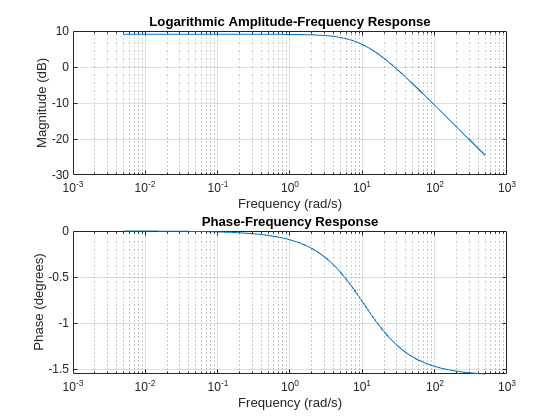

magnitude_dB = 20 * log10(a);

% Построение графиков вручную (опционально)
figure;
subplot(2,1,1);
semilogx(omega, magnitude_dB); % ЛАЧХ
xlabel('Frequency (rad/s)');
ylabel('Magnitude (dB)');
title('Logarithmic Amplitude-Frequency Response');
grid on;

subplot(2,1,2);
semilogx(omega, phi); % ФЧХ
xlabel('Frequency (rad/s)');
ylabel('Phase (degrees)');
title('Phase-Frequency Response');
grid on;

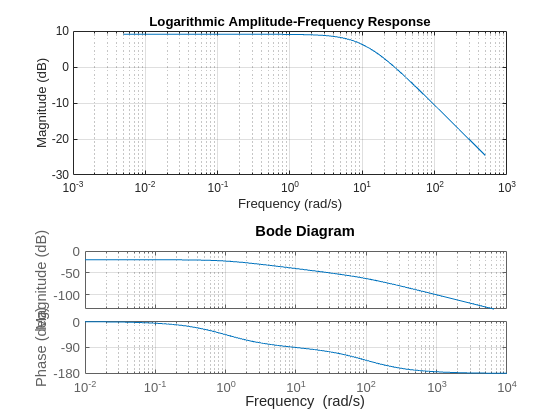

ex_sys = tf([10], [1, 101, 100]);
bode(ex_sys);
grid on;   % Добавить сетку для удобства чтения графиков

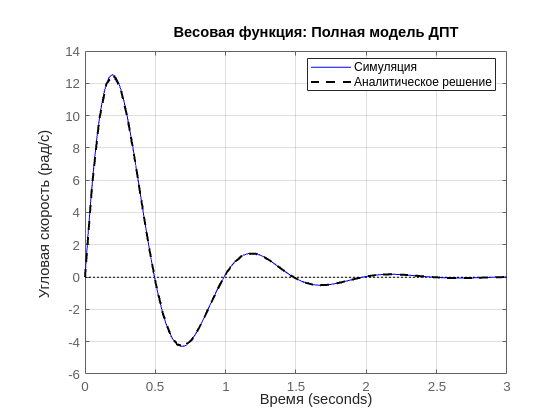


% ---- График импульсного отклика для полной модели ----
figure;
impulse(sys_full, 'b');
hold on;
plot(t, omega_anal_full_impulse, 'k--', 'LineWidth', 1.5); % Аналитическое решение
title('Весовая функция: Полная модель ДПТ');
legend('Симуляция', 'Аналитическое решение', "Location", "best");
xlabel('Время');
ylabel('Угловая скорость (рад/с)');
grid on;
exportgraphics(gcf, 'figs/task_2_impl.png', 'Resolution', 300);

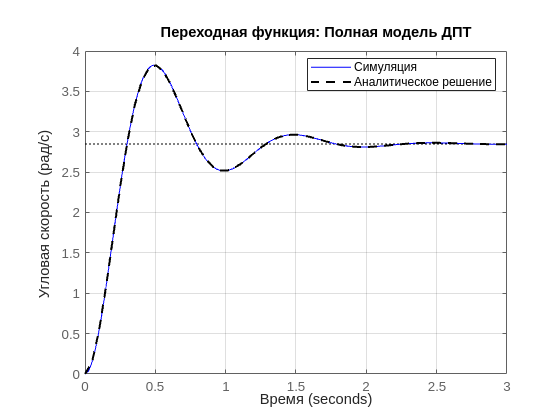


% ---- График переходного отклика для полной модели ----
figure;
step(sys_full, 'b');
hold on;
plot(t, omega_anal_full_step, 'k--', 'LineWidth', 1.5); % Аналитическое решение
title('Переходная функция: Полная модель ДПТ');
legend('Симуляция', 'Аналитическое решение', "Location", "best");
xlabel('Время');
ylabel('Угловая скорость (рад/с)');
grid on;
exportgraphics(gcf, 'figs/task_2_step.png', 'Resolution', 300);

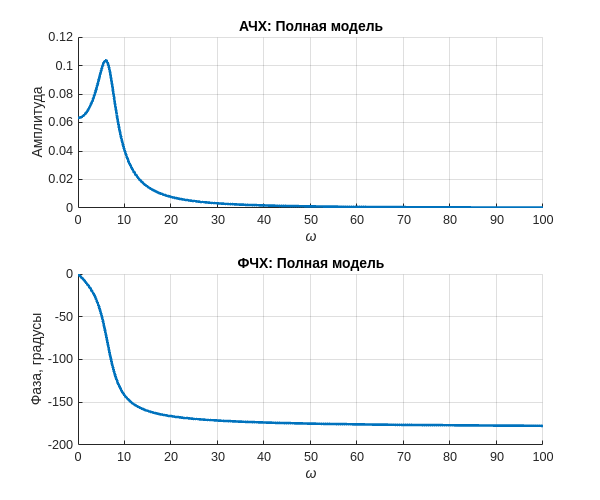

% ---- График АФЧХ для полной модели ----
omega = linspace(0, 100, 100000);

A = K./sqrt(2.166^2+(omega-6.352).^2)./sqrt(2.166^2+(omega+6.352).^2);
phi = -atan2((omega-6.352), 2.166) - atan2((omega+6.352), 2.166);

figure('Position', [0 0 600 500]);

subplot(2, 1, 1)
hold on;
plot(omega, A, 'LineWidth', 2);
title('АЧХ: Полная модель');
xlabel('\omega');
ylabel('Амплитуда');
grid on;

subplot(2, 1, 2)
hold on;
plot(omega, phi/pi*180, 'LineWidth', 2);
title('ФЧХ: Полная модель');
xlabel('\omega');
ylabel('Фаза, градусы');
grid on;

exportgraphics(gcf, 'figs/task_2_АФЧХ.png', 'Resolution', 300);

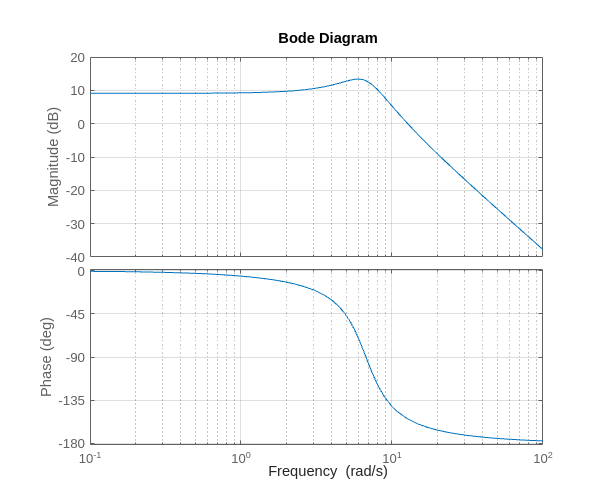

% Построение Bode Plot
figure('Position', [0 0 600 500]);
bode(sys_full);
grid on;   % Добавить сетку для удобства чтения графиков
exportgraphics(gcf, 'figs/task_2_ЛАФЧХ.png', 'Resolution', 300);

## Конденсируй-умножай

% Параметры системы
C = 332e-6; % Емкость, Ф
K = 1 / C;  % Коэффициент усиления для интегрирующего звена

% Параметры для моделирования
t_end = 1;    % Время симуляции, с
omega_max = 1e3; % Максимальная частота для анализа, рад/с

% Временная шкала
t = linspace(0, t_end, 1000);

%% 1. Инженерная форма передаточной функции
sys = tf(K, [1 0]); % W(s) = K / s

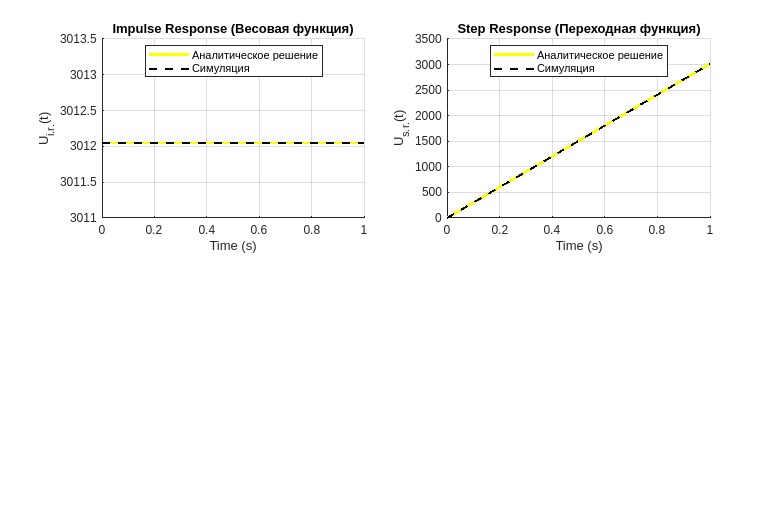

%% 2. Весовая функция (импульсная переходная характеристика)
U_ir = K * ones(size(t)); % U_{i.r.}(t) = K

% Симуляция импульсной характеристики
[impulse_sim, t_imp] = impulse(sys, t_end);

% Построение графика весовой функции
figure('Position', [100, 100, 900, 600]);
subplot(2,2,1);
hold on;
plot(t_imp, impulse_sim, 'y', 'LineWidth', 2);
plot(t, U_ir, 'k--', 'LineWidth', 1.5); % Аналитическое решение
grid on;
xlabel('Time (s)');
ylabel('U_{i.r.}(t)');
title('Impulse Response (Весовая функция)');
legend('Аналитическое решение', 'Симуляция', 'Location', 'best');

%% 3. Переходная функция (ступенчатая переходная характеристика)
U_sr = K * t; % U_{s.r.}(t) = K * t

% Симуляция переходной характеристики
[step_sim, t_step] = step(sys, t_end);

% Построение графика переходной функции
subplot(2,2,2);
hold on;
plot(t_step, step_sim, 'y', 'LineWidth', 2);
plot(t, U_sr, 'k--', 'LineWidth', 1.5); % Аналитическое решение
grid on;
xlabel('Time (s)');
ylabel('U_{s.r.}(t)');
title('Step Response (Переходная функция)');
legend('Аналитическое решение', 'Симуляция', 'Location', 'best');

exportgraphics(gcf, 'figs/task_3_impl_step.png', 'Resolution', 300);

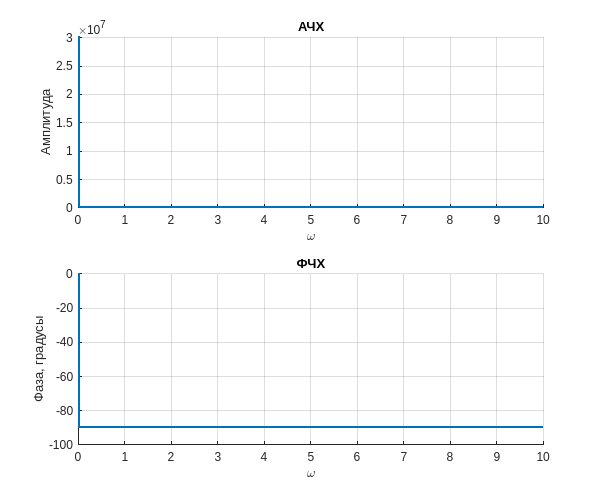

%% 4. Частотные характеристики

% ---- График АФЧХ для полной модели ----
omega = linspace(0, 10, 100000);

W_jw = K ./ (1j * omega); % W(jω)

% Амплитудно-частотная характеристика (АЧХ)
A_w = abs(W_jw); % A(ω) = |W(jω)|

% Фазо-частотная характеристика (ФЧХ)
phi_w = angle(W_jw); % φ(ω) = arg(W(jω))

figure('Position', [0 0 600 500]);

subplot(2, 1, 1)
hold on;
plot(omega, A_w, 'LineWidth', 2);
title('АЧХ');
xlabel('\omega');
ylabel('Амплитуда');
grid on;

subplot(2, 1, 2)
hold on;
plot(omega, phi_w/pi*180, 'LineWidth', 2);
title('ФЧХ');
xlabel('\omega');
ylabel('Фаза, градусы');
grid on;

exportgraphics(gcf, 'figs/task_3_АФЧХ.png', 'Resolution', 300);

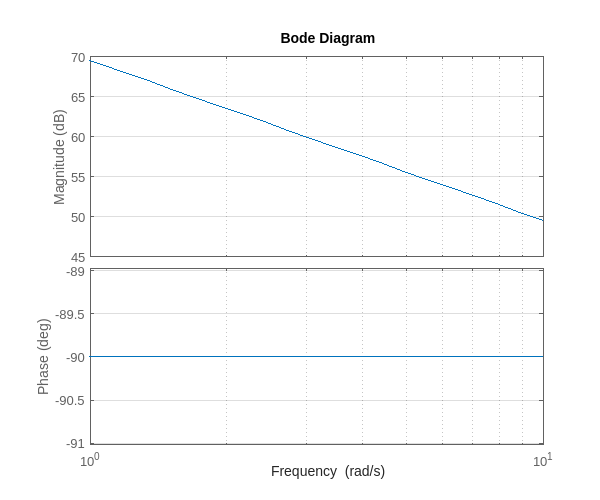

Коэффициент усиления K = 3012.05


Весовая функция: U_{i.r.}(t) = K


Переходная функция: U_{s.r.}(t) = Kt


АЧХ: A(ω) = K / ω


ФЧХ: φ(ω) = -π/2 (для положительных ω)


% ---- Построение Bode Plot ----
figure('Position', [0 0 600 500]);
bode(sys);
grid on;   % Добавить сетку для удобства чтения графиков
exportgraphics(gcf, 'figs/task_3_ЛАФЧХ.png', 'Resolution', 300);

## Пружина

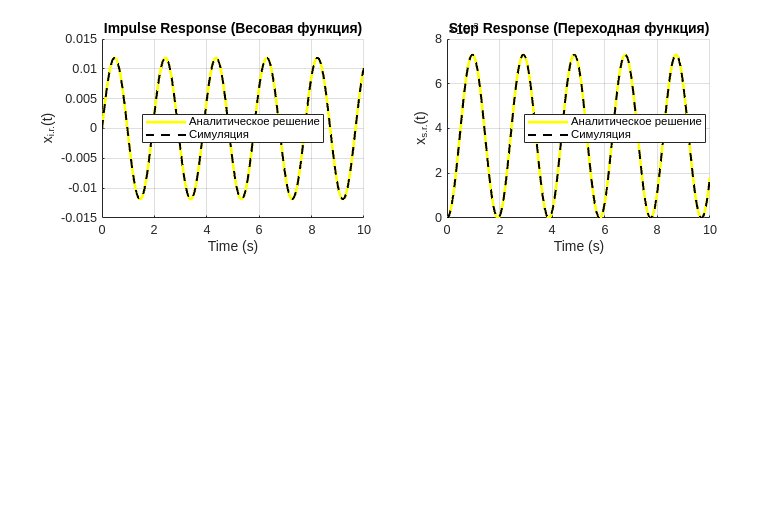

% Параметры системы
m = 26;    % масса, кг
k = 274;   % жесткость пружины, Н/м
T = sqrt(m/k); % Постоянная времени
K = 1/k;

% Определение передаточной функции системы
num = 1;
den = [m, 0, k];
sys = tf(num, den);

% Временная шкала
t_end = 10; % время симуляции
t = linspace(0, t_end, 1000);

%% Весовая функция
[impulse_sim, t_imp] = impulse(sys, t);

x_ir = K/T*sin(t/T);

% Построение графиков для весовой функции
figure('Position', [100, 100, 900, 600]);
subplot(2,2,1);
hold on;
plot(t_imp, impulse_sim, 'y', 'LineWidth', 2);
plot(t, x_ir, 'k--', 'LineWidth', 1.5); % Аналитическое решение
grid on;
xlabel('Time (s)');
ylabel('x_{i.r.}(t)');
title('Impulse Response (Весовая функция)');
legend('Аналитическое решение', 'Симуляция', 'Location', 'best');

%% Переходная характеристика
[step_sim, t_step] = step(sys, t);

x_sr = K*(1-cos(t/T));

subplot(2,2,2);
hold on;
plot(t_step, step_sim, 'y', 'LineWidth', 2);
plot(t, x_sr, 'k--', 'LineWidth', 1.5); % Аналитическое решение
grid on;
xlabel('Time (s)');
ylabel('x_{s.r.}(t)');
title('Step Response (Переходная функция)');
legend('Аналитическое решение', 'Симуляция', 'Location', 'best');

exportgraphics(gcf, 'figs/task_4_impl_step.png', 'Resolution', 300);

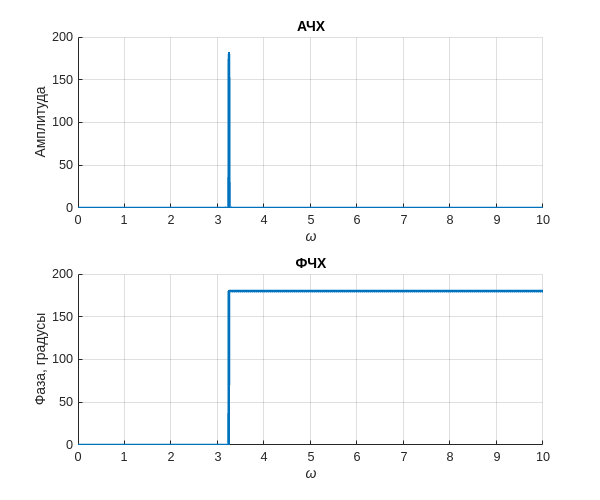

%% 4. Частотные характеристики

% ---- График АФЧХ для полной модели ----
omega = linspace(0, 10, 100000);

% Амплитудно-частотная характеристика (АЧХ)
A_w = abs(K./(1-T^2*omega.^2));

% Фазо-частотная характеристика (ФЧХ)
phi_w = atan2(0, K./(1-T^2*omega.^2));

figure('Position', [0 0 600 500]);

subplot(2, 1, 1)
hold on;
plot(omega, A_w, 'LineWidth', 2);
title('АЧХ');
xlabel('\omega');
ylabel('Амплитуда');
grid on;

subplot(2, 1, 2)
hold on;
plot(omega, phi_w/pi*180, 'LineWidth', 2);
title('ФЧХ');
xlabel('\omega');
ylabel('Фаза, градусы');
grid on;

exportgraphics(gcf, 'figs/task_4_АФЧХ.png', 'Resolution', 300);

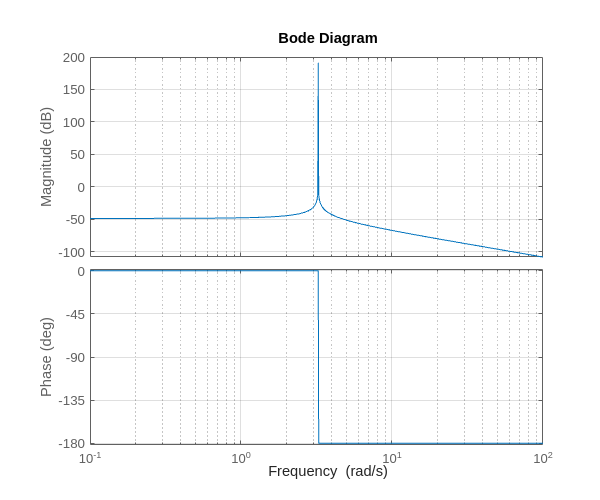

% ---- Построение Bode Plot ----
figure('Position', [0 0 600 500]);
bode(sys);
grid on;   % Добавить сетку для удобства чтения графиков
exportgraphics(gcf, 'figs/task_4_ЛАФЧХ.png', 'Resolution', 300);

## ОУ

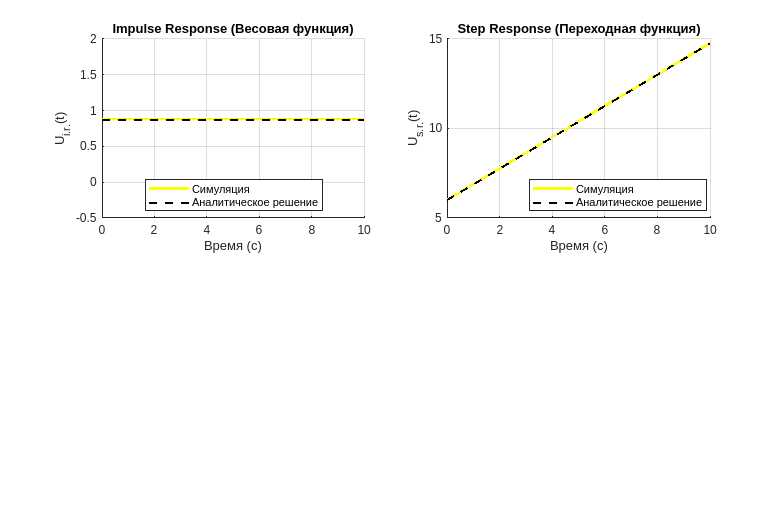

% Параметры ПИ-регулятора
R1 = 3440;         % Ом
R2 = 20639;        % Ом
C = 332e-6;        % Ф

% Вычисление инженерных параметров
K = 1/(R1 * C);    % Усиление
T = R2 * C;        % Постоянная времени

% Определение передаточной функции изодромного звена
num = [K * T, K];  % Числитель ПФ
den = [1, 0];      % Знаменатель ПФ
sys = tf(num, den);

% Временная шкала
t_end = 10; % Время симуляции
t = linspace(0, t_end, 1000);

%% Весовая функция
[impulse_sim, t_imp] = impulse(sys, t);
U_ir = K * ones(size(t));

figure('Position', [100, 100, 900, 600]);
subplot(2,2,1);
hold on;
plot(t_imp, impulse_sim, 'y', 'LineWidth', 2);
plot(t, U_ir, 'k--', 'LineWidth', 1.5); % Аналитическое решение
grid on;
xlabel('Время (с)');
ylabel('U_{i.r.}(t)');
title('Impulse Response (Весовая функция)');
legend('Симуляция', 'Аналитическое решение', 'Location', 'best');

%% Переходная функция
[step_sim, t_step] = step(sys, t);
U_sr = K * (T + t);

subplot(2,2,2);
hold on;
plot(t_step, step_sim, 'y', 'LineWidth', 2);
plot(t, U_sr, 'k--', 'LineWidth', 1.5); % Аналитическое решение
grid on;
xlabel('Время (с)');
ylabel('U_{s.r.}(t)');
title('Step Response (Переходная функция)');
legend('Симуляция', 'Аналитическое решение', 'Location', 'best');
exportgraphics(gcf, 'figs/task_5_impl_step.png', 'Resolution', 300);

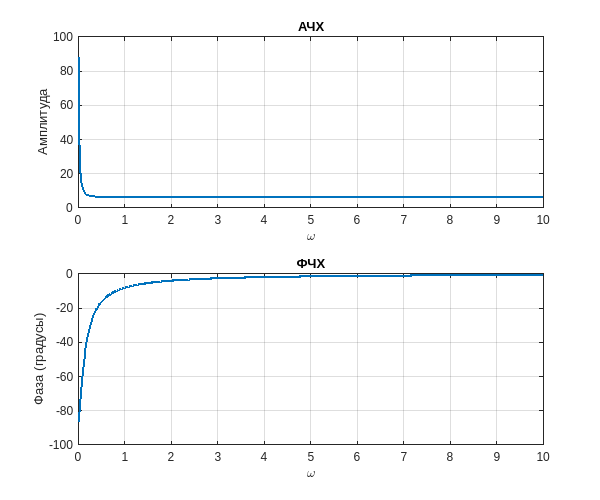

%% Частотные характеристики
omega = linspace(0.01, 10, 1000);
A_w = K*sqrt(T^2+1./omega.^2);
phi_w = atan(-1./(T*omega));

figure('Position', [0 0 600 500]);
subplot(2, 1, 1);
plot(omega, A_w, 'LineWidth', 2);
title('АЧХ');
xlabel('\omega');
ylabel('Амплитуда');
grid on;

subplot(2, 1, 2);
plot(omega, phi_w * (180/pi), 'LineWidth', 2);
title('ФЧХ');
xlabel('\omega');
ylabel('Фаза (градусы)');
grid on;
exportgraphics(gcf, 'figs/task_5_АФЧХ.png', 'Resolution', 300);

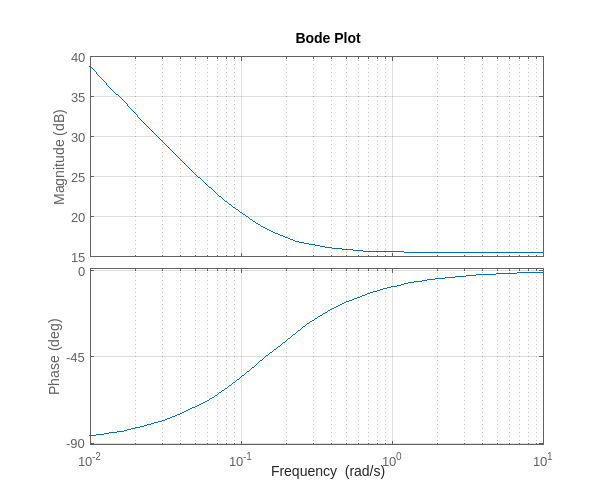

% Bode Plot
figure('Position', [0 0 600 500]);
bode(sys);
grid on;
title('Bode Plot');
exportgraphics(gcf, 'figs/task_5_ЛАФЧХ.png', 'Resolution', 300);